# Newton’s Divided-Difference Formula

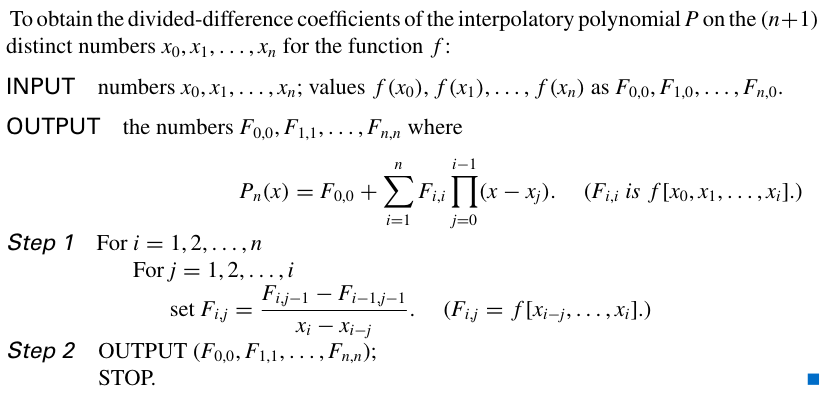

Clear Previous Data

clc;
clear;

Input the initial point:

X = [1.0 1.3 1.6 1.9]; % Initial Value
xvalue=1.5;            % Approximation Value
n = size(X);
n = n(2);
F=[];
for i = 1:n
    Y(i)=func(X(i));   %Exact value for Y
end

for i = 1:n
    Yd(i)=funcdiff(X(i));   %Exact value for Y
end

## Iteration Rule

Start build the interated Interpolation:


$$F_{i, j}=\frac{F_{i, j-1}-F_{i-1, j-1}}{x_{i}-x_{i-j}}$$


START=0 +1;
END=2*(n-1)+1 +1;
z(START:END)=0;
Q(START:END,START:END)=0;

for i = 0:n-1
    I=i+1;
    z(2*I-1)=X(I);
    z(2*I)=X(I);
    Q(2*I-1,0 +1)=Y(I);
    Q(2*I,0 +1)=Y(I);
    Q(2*I,1 +1)=Yd(I);


    if i ~= 0
        Q(2*i +1,1 +1)=(Q(2*i+1,0 +1)-Q(2*i-1+1,0+1))/(z(2*i+1)-z(2*i-1+1));
    end
end


for i= 2:2*(n-1)+1
    I=i+1;
    for j = 2:i
        J=j+1;
        Q(I,J)=(Q(I,J-1)-Q(I-1,J-1))/(z(I)-z(I-J+1));
    end
end



## Appendix Function

function y = func(x)
    y=x^2;
end

function y = funcdiff(x)
    y=2*x;
end